依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases/tag/v17.1.0)

饼图，显示光声和声光的Transfer命中错失比例

DataSet=TransferLearning.FullCalcium;
CalciumBehavior=structfun(@(T)height(unique(T)),DataSet.TableQuery("TrialUID",UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'HitMissPie')),UniformOutput=false);

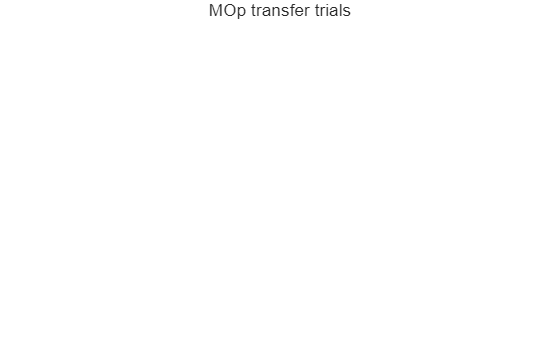

figure;
Layout=tiledlayout(1,2,TileSpacing='tight',Padding='tight');
nexttile;
piechart([CalciumBehavior.Light_water_hit,CalciumBehavior.Light_water_miss],["Hit","Miss"]);
title("Learned light-water");
nexttile;
piechart([CalciumBehavior.Audio_water_hit,CalciumBehavior.Audio_water_miss],["Hit","Miss"]);
title("Transfer audio-water");
title(Layout,'MOp transfer trials');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('HitMissPie.svg'),'-dsvg');